# レギュラーシーズンのMasseyレーティングからプレイオフを予測する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all

データを読み込む(prog_NBADataConcatenation.mlxを実行しておく)

load('../data/NBAResults.mat');

2018-19シーズンのチームと試合を抽出する．

seasonStartYearVal=2018;
ind = tbl_teams.SeasonStartYear==seasonStartYearVal;
tbl_teams_tmp=tbl_teams(ind,:);
numTeams=size(unique(tbl_teams_tmp.TeamName),1);

試合は訓練用(train)とテスト用(test)に分ける

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isRegular;
tbl_results_train=tbl_results(ind,:);

ind = tbl_results.SeasonStartYear==seasonStartYearVal ...
    & tbl_results.isPlayoff;
tbl_results_test=tbl_results(ind,:);

### 比較のために勝敗や得失点も集計する

勝，負試合数，および得失点を集計する

集計用の変数を準備する

Wins=zeros(size(tbl_teams_tmp,1),1);
Loses=zeros(size(tbl_teams_tmp,1),1);
ScoresFor=zeros(size(tbl_teams_tmp,1),1);
ScoresAgainst=zeros(size(tbl_teams_tmp,1),1);

for n1=1:size(tbl_results_train,1)

それぞれの試合で両チームが何番に対応するかを見つける

    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));

各チームの得失点を加える

    ScoresFor(TeamANum)=ScoresFor(TeamANum)+tbl_results_train.HomeScore(n1);
    ScoresFor(TeamBNum)=ScoresFor(TeamBNum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamANum)=ScoresAgainst(TeamANum)+tbl_results_train.AwayScore(n1);
    ScoresAgainst(TeamBNum)=ScoresAgainst(TeamBNum)+tbl_results_train.HomeScore(n1);

得点の大小で場合分けし，勝・引分・負それぞれに加える

    if tbl_results_train.HomeScore(n1)>tbl_results_train.AwayScore(n1)
        Wins(TeamANum)=Wins(TeamANum)+1;
        Loses(TeamBNum)=Loses(TeamBNum)+1;
    elseif tbl_results_train.HomeScore(n1)<tbl_results_train.AwayScore(n1)
        Loses(TeamANum)=Loses(TeamANum)+1;
        Wins(TeamBNum)=Wins(TeamBNum)+1;
    end
end

勝率，得点割合の列を追加する

WinRatio=Wins./(Wins+Loses);
ScoreRatio=ScoresFor./(ScoresFor+ScoresAgainst);
tbl_teams_tmp=addvars(tbl_teams_tmp, WinRatio, ScoreRatio);

勝率→得失点割合の優先順でソートし，その順位を追加する

tbl_teams_tmp=sortrows(tbl_teams_tmp,{'WinRatio','ScoreRatio'},'descend');
RankByWins=(1:size(tbl_teams_tmp,1))';
tbl_teams_tmp=addvars(tbl_teams_tmp,RankByWins);

### Masseyレーティングを算出する

X=zeros(size(tbl_results_train,1), size(tbl_teams_tmp,1));  %係数行列
y=zeros(size(tbl_results_train,1),1);
for n1=1:size(tbl_results_train,1)
    TeamANum=find(tbl_teams_tmp.TeamName==tbl_results_train.Home(n1));
    TeamBNum=find(tbl_teams_tmp.TeamName==tbl_results_train.Away(n1));
    ScoreA=tbl_results_train.HomeScore(n1);
    ScoreB=tbl_results_train.AwayScore(n1);
    X(n1,TeamANum)=1;X(n1,TeamBNum)=-1;
    y(n1)=ScoreA-ScoreB;
end

RatingMassey=pinv(X)*y

RatingMassey =     8.0457
    5.4910
    6.4230
    4.1978
    4.9655
    4.4359
    2.2577
    5.2873
    3.8995
    3.5594


tbl_teams_tmp=addvars(tbl_teams_tmp, RatingMassey);

勝率順位とMasseyレーティングの順位相関を計算する

corr(tbl_teams_tmp.WinRatio, tbl_teams_tmp.RatingMassey,'type','Kendall')

ans = 0.8963

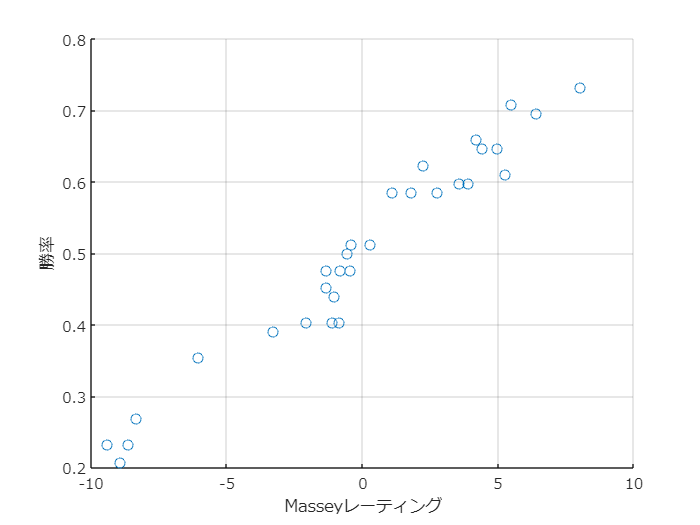

figure
scatter(tbl_teams_tmp.RatingMassey, tbl_teams_tmp.WinRatio);
grid on;
set(gca,'fontname','メイリオ');
xlabel('Masseyレーティング');ylabel('勝率');
exportgraphics(gcf,'fig_MasseyAndWinRatio.pdf');

プレイオフの結果を予測する

予測と実際の結果を格納する変数を定義する

PredictionByWin=zeros(size(tbl_results_test,1),1);
PredictionByMassey=zeros(size(tbl_results_test,1),1);
ActualWin=zeros(size(tbl_results_test,1),1);
plotData=[];
for n1=1:size(tbl_results_test,1)
   if tbl_results_test.HomeScore(n1)>tbl_results_test.AwayScore(n1)
        ActualWin(n1)=1;    %ホーム勝利を1と定義する
   else
        ActualWin(n1)=0;
   end

   TeamANum=find(tbl_teams_tmp.TeamName== tbl_results_test.Home(n1));
   TeamBNum=find(tbl_teams_tmp.TeamName== tbl_results_test.Away(n1));
   TeamARank=tbl_teams_tmp.RankByWins(TeamANum);
   TeamBRank=tbl_teams_tmp.RankByWins(TeamBNum);
   if TeamARank<TeamBRank
       PredictionByWin(n1)=1;
   else
       PredictionByWin(n1)=0;
   end

   TeamAMassey=tbl_teams_tmp.RatingMassey(TeamANum);
   TeamBMassey=tbl_teams_tmp.RatingMassey(TeamBNum);
   if TeamAMassey>TeamBMassey
       PredictionByMassey(n1)=1;
   else
       PredictionByMassey(n1)=0;
   end
   plotData=[plotData;TeamAMassey-TeamBMassey ...
       tbl_results_test.HomeScore(n1)-tbl_results_test.AwayScore(n1)];
end

予測正解を判定する．

isPredictionCorrectByWin= ActualWin==PredictionByWin;
isPredictionCorrectByMassey= ActualWin==PredictionByMassey;

予測正解率を算出する

predictionAccuracyByWin=mean(isPredictionCorrectByWin)

predictionAccuracyByWin = 0.6951

predictionAccuracyByMassey=mean(isPredictionCorrectByMassey)

predictionAccuracyByMassey = 0.6463

結果と予測，予測正解かどうかを図示する

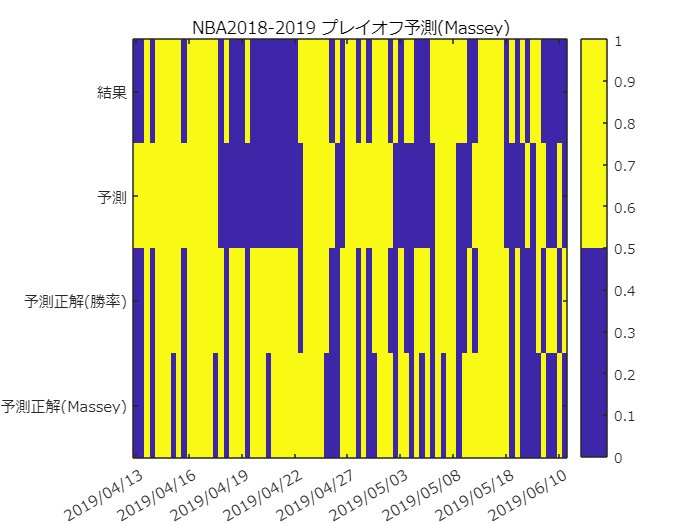

figure
imagesc([ActualWin PredictionByWin isPredictionCorrectByWin isPredictionCorrectByMassey]');
cmap=colormap(gca);
colormap(cmap([1,end],:));
colorbar;
set(gca,'fontname','メイリオ');
xticks(1:10:size(tbl_results_test,1));
xticklabels(string(tbl_results_test.Date(1:10:end)));
yticks(1:4);
yticklabels({'結果','予測','予測正解(勝率)','予測正解(Massey)'});
title('NBA2018-2019 プレイオフ予測(Massey)');
exportgraphics(gcf,'fig_NBA20182019PredictionByMassey.pdf');

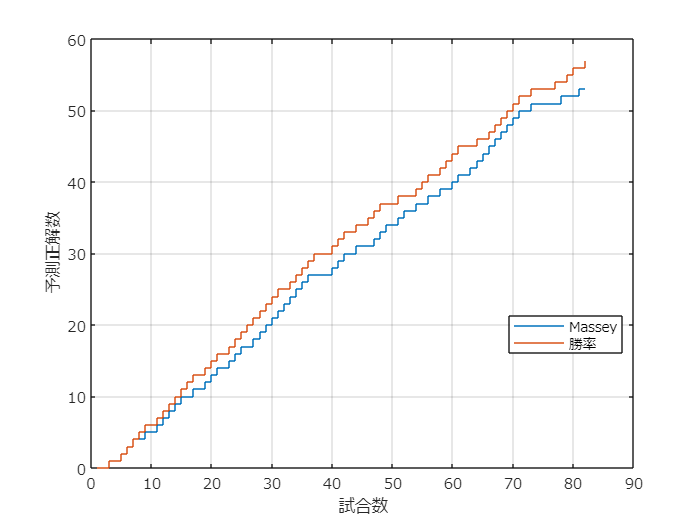

figure
stairs([cumsum(isPredictionCorrectByMassey) cumsum(isPredictionCorrectByWin)]);
legend({'Massey','勝率'},'Location','best')
grid on;
set(gca,'fontname','メイリオ');
xlabel('試合数');ylabel('予測正解数');
exportgraphics(gcf,'fig_NBA20182019CorrectPredictionsByMassey.pdf');

Masseyレーティング差と実得点差の差の二乗平均

mean((plotData(:,1)-plotData(:,2)).^2)

ans = 179.0073

sqrt(ans)

ans = 13.3794

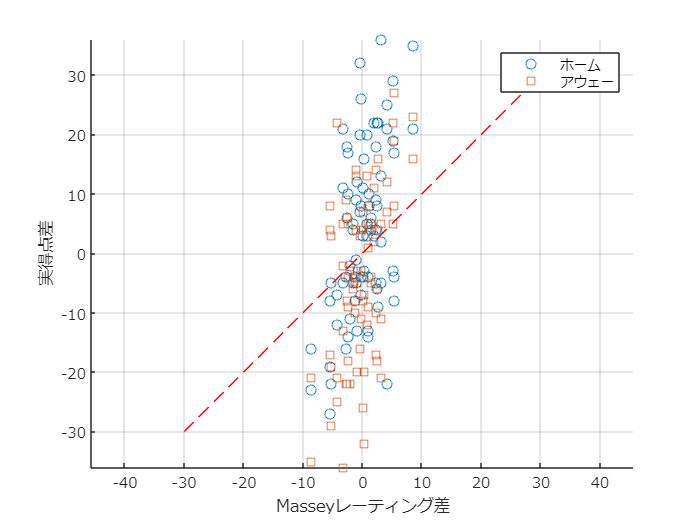

figure
scatter(plotData(:,1), plotData(:,2));
hold on;
scatter(-plotData(:,1), -plotData(:,2),'s');
grid on;axis equal;
set(gca,'fontname','メイリオ');
xlabel('Masseyレーティング差');ylabel('実得点差');
plot([-30 30],[-30 30],'r--');
legend({'ホーム','アウェー'});
exportgraphics(gcf,'fig_NBA20182019MasseyDiffAndScoreDiff.pdf')